clear all

% Params
fs = 8e3;

load('LP_opt16.mat')
[LP_B, LP_A] = sos2tf(SOS_LP_opt16, G_LP_opt16)

LP_B =     0.0062   -0.0257    0.0779   -0.1514    0.2367   -0.2641    0.2229   -0.0795   -0.0795    0.2229   -0.2641    0.2367   -0.1514    0.0779   -0.0257    0.0062


LP_A =     1.0000   -8.3516   36.8415 -109.8730  244.5796 -426.8146  600.2528 -690.5169  654.0010 -509.6467  324.2676 -165.6964   66.0262  -19.4688    3.8310   -0.3859


load('BP_opt14.mat')
[BP_B, BP_A] = sos2tf(SOS_BP_opt14, G_BP_opt14)

BP_B =     0.0076   -0.0000   -0.0022   -0.0000    0.0160   -0.0000   -0.0117    0.0000    0.0117    0.0000   -0.0160    0.0000    0.0022    0.0000   -0.0076


BP_A =     1.0000    0.0000    4.0731   -0.0000    8.5964   -0.0000   11.3703   -0.0000   10.0829   -0.0000    5.9468   -0.0000    2.1695   -0.0000    0.3836


%fvtool(BP_B,BP_A);
BP_B = [BP_B 0]

BP_B =     0.0076   -0.0000   -0.0022   -0.0000    0.0160   -0.0000   -0.0117    0.0000    0.0117    0.0000   -0.0160    0.0000    0.0022    0.0000   -0.0076         0


BP_A = [BP_A 0]

BP_A =     1.0000    0.0000    4.0731   -0.0000    8.5964   -0.0000   11.3703   -0.0000   10.0829   -0.0000    5.9468   -0.0000    2.1695   -0.0000    0.3836         0


%fvtool(BP_B,BP_A);
load('HP_opt16.mat')
[HP_B, HP_A] = sos2tf(SOS_HP_opt16, G_HP_opt16)

HP_B =     0.0765   -0.7006    3.3267  -10.6022   25.0948  -46.4223   69.0608  -83.9346   83.9346  -69.0608   46.4223  -25.0948   10.6022   -3.3267    0.7006   -0.0765


HP_A =     1.0000   -5.0010   16.1322  -35.3297   60.6076  -81.3530   89.8695  -79.9969   58.8029  -33.6177   14.8272   -3.6140   -0.1954    0.9537   -0.4230    0.1424


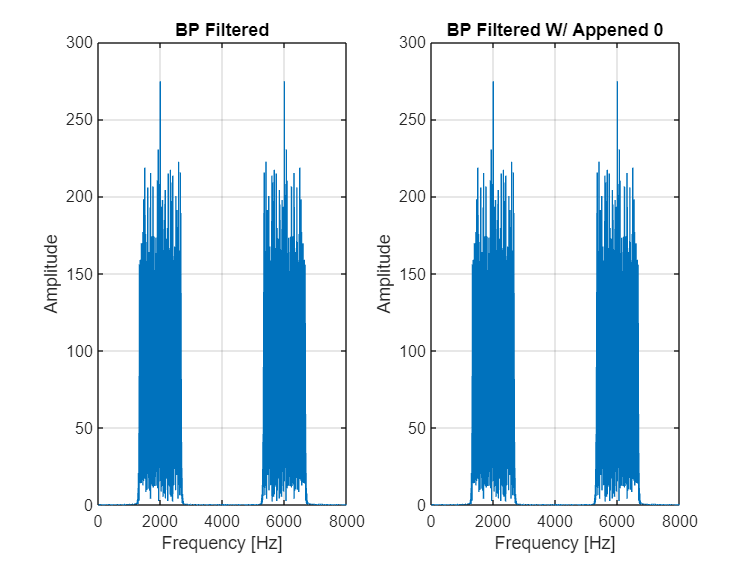


q_float = quantizer('single'); % Convert to signle precision
BP_A_q = quantize(q_float, BP_A);
BP_B_q = quantize(q_float, BP_B);

x = wgn(10000,1,0); % Gaussian noise (mean = 0, std = 1)
y_bp = filter(BP_B_q, BP_A_q, x);
y_bp2 = filter(BP_B_q, BP_A_q, x);

figure;
subplot(1,2,1);
plot(fs*[0:1/length(y_bp):(length(y_bp)-1)/length(y_bp)], abs(fft(y_bp)));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('BP Filtered'); % Two-sided
grid on;

subplot(1,2,2);
plot(fs*[0:1/length(y_bp2):(length(y_bp2)-1)/length(y_bp2)], abs(fft(y_bp2)));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('BP Filtered W/ Appened 0'); % Two-sided
grid on;

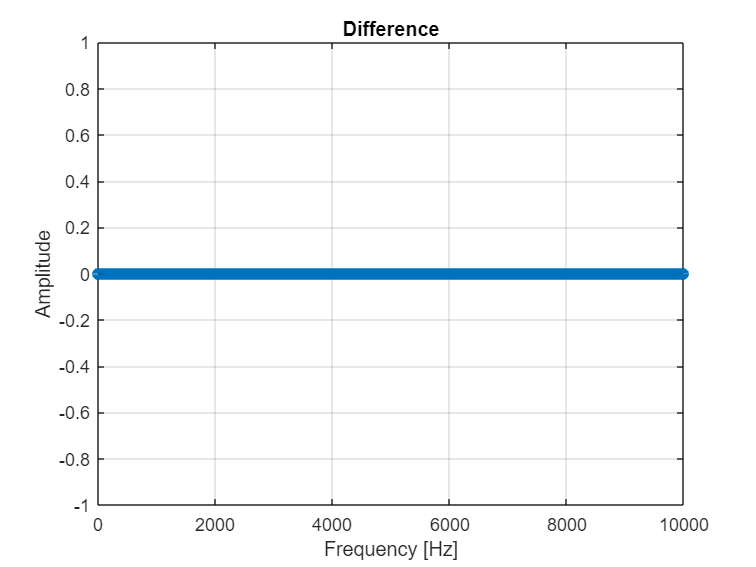


figure;
stem(abs(y_bp2-y_bp));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('Difference');
grid on;